



%InteriorWallTemp = InteriorWallEnergy/MassofWall*SpecificHeatW%all
ThicknessofWall = 0.1651;% (meters) we divide the wall by 2 as we consider thewall as two stocks for the inner and outer
DensityofWall = 22;% (kg/m3) based on density of rockwool TODO NOT REAL NUMBER
SpecificHeatWall = 700;%(J/K/kg)
%OuterWallTemp = OuterWallEnergy/MassofWall*SpecificHeatWall

%InteriorWindowTemp = InteriorWindowEnergy/MassofWindow*SpecificHeatWindow;

DensityofWindow = 2500;% (kg/m3) based on density of rockwool
SpecificHeatWindow = 840;% (J/K/kg)
%OuterWindowTemp = OuterWindowEnergy/MassofWindow*SpecificHeatWindow
%MassofWindow = DensityofWindow * AreaofWindow * ThicknessofWindow/2
OutsideInitialTemperature = 288.706;% (K)
WindowResistance = 1/.28;% (d/k)
WallResistance = 19.93;% (d/k)

TotalHouseArea = 442;% (m2)
AreaofWindow = 10%-400;% (m2) will sweep (start at 10)

AreaofWindow = 10

AreaofWall = TotalHouseArea - AreaofWindow;% (m2)
WallThickness = .1651;% (m)
ThicknessofWindow = 0.006;% (meters)
HouseVolume = 743 ;%m3
InsideInitialTemperature = 25;% (K)
MassofAir = 910.175;% (kg)
SpecificHeatAir = 1000;% (J/K/kg)
%AirTemp = InsideEnergy/MassofAir*SpecificHeatAir;%
MassofWindow = DensityofWindow * AreaofWindow * ThicknessofWindow;
MassofWall = DensityofWall * AreaofWall * ThicknessofWall

MassofWall = 1.5691e+03

InsideInitialEnergy = MassofAir * SpecificHeatAir * InsideInitialTemperature;%
%InsideEnergy = determined by ode (J)
InnerWallInitialEnergy = MassofWall/2 * SpecificHeatWall * InsideInitialTemperature

InnerWallInitialEnergy = 13729716

%InteriorWallEnergy = determined by ode (J)
InnerWindowInitialEnergy = MassofWindow/2 * SpecificHeatWindow * InsideInitialTemperature

InnerWindowInitialEnergy = 1575000

%InteriorWindowEnergy = determined by ode (J)
OuterWindowInitialEnergy = MassofWindow/2 * SpecificHeatWindow * OutsideInitialTemperature

OuterWindowInitialEnergy = 18188478

%OuterWindowEnergy = determined by ode (J)
OuterWallInitialEnergy = MassofWall/2 * SpecificHeatWall * OutsideInitialTemperature

OuterWallInitialEnergy = 1.5855e+08

%OuterWallEnergy = determined by ode (J)



OutsideAirTemp              =   15.5

OutsideAirTemp = 15.5000

Inside2InnerWallh           =   13.5

Inside2InnerWallh = 13.5000

h1=13.5

h1 = 13.5000

h2=137.5

h2 = 137.5000

r=WallResistance

r = 19.9300

Inside2InnerWindowh         =   13.5

Inside2InnerWindowh = 13.5000

HeatCapacityofAir           =   MassofAir*SpecificHeatAir

HeatCapacityofAir = 910175

HeatCapacityofInteriorWall  =   MassofWall*SpecificHeatWall/2

HeatCapacityofInteriorWall = 5.4919e+05

HeatCapacityofInteriorWindow=   MassofWindow*SpecificHeatWindow/2

HeatCapacityofInteriorWindow = 63000

HeatCapacityofOuterWall     =   MassofWall*SpecificHeatWall/2

HeatCapacityofOuterWall = 5.4919e+05

HeatCapacityofOuterWindow   =   MassofWindow*SpecificHeatWindow/2

HeatCapacityofOuterWindow = 63000

Inside2OuterWallr           =   WallResistance/5.5556

Inside2OuterWallr = 3.5874

Inside2OuterWindowr         =   WindowResistance/5.5556

Inside2OuterWindowr = 0.6429

OuterWall2Outsideh          =   137.5

OuterWall2Outsideh = 137.5000

OuterWindow2Outsideh        =   137.5

OuterWindow2Outsideh = 137.5000

absorptionefficiency = .32

absorptionefficiency = 0.3200

Insolation = 187.5

Insolation = 187.5000


InsolationInput =   absorptionefficiency * Insolation

InsolationInput = 60

blah blah blah

ode 

deltatime = [0;200]

deltatime =      0
   200


Uinit = [InsideInitialEnergy; InnerWallInitialEnergy; InnerWindowInitialEnergy; OuterWindowInitialEnergy; OuterWallInitialEnergy]

Uinit = 	1.0e+08 *

    0.2275
    0.1373
    0.0158
    0.1819
    1.5855


dT = 60*60% seconds to hours

dT = 3600

[t,m] = ode45(@(T,U) housestep(T,U,OutsideAirTemp,InsolationInput,AreaofWall,AreaofWindow,Inside2InnerWallh,Inside2InnerWindowh,OuterWall2Outsideh,OuterWindow2Outsideh,HeatCapacityofAir,HeatCapacityofInteriorWall,HeatCapacityofInteriorWindow,HeatCapacityofOuterWall,HeatCapacityofOuterWindow,Inside2OuterWallr,Inside2OuterWindowr),deltatime,Uinit)

en2inwa = 0

intemp = 25

inwalltemp = 25

en2inwi = 0

en2ouwa = 3.1756e+04

en2ouwi = 4.1021e+03

en2owasd = -1.6228e+07

en2owisd = -3.7566e+05

InsideEnergy = 600

InteriorWallEnergy = -3.1756e+04

InteriorWindowEnergy = -4.1021e+03

OuterWindowEnergy = 1.6260e+07

OuterWallEnergy = 3.7976e+05

en2inwa = -15.3334

intemp = 25.0000

inwalltemp = 24.9974

en2inwi = -0.3992

en2ouwa = 3.1760e+04

en2ouwi = 4.2827e+03

en2owasd = -1.6230e+07

en2owisd = -3.9161e+05

InsideEnergy = 615.7325

InteriorWallEnergy = -3.1776e+04

InteriorWindowEnergy = -4.2831e+03

OuterWindowEnergy = 1.6262e+07

OuterWallEnergy = 3.9590e+05

en2inwa = -23.0155

intemp = 25.0000

inwalltemp = 24.9961

en2inwi = -0.6185

en2ouwa = 3.1762e+04

en2ouwi = 4.3730e+03

en2owasd = -1.6231e+07

en2owisd = -3.9959e+05

InsideEnergy = 623.6340

InteriorWallEnergy = -3.1785e+04

InteriorWindowEnergy = -4.3736e+03

OuterWindowEnergy = 1.6263e+07

OuterWallEnergy = 4.0396e+05

en2inwa = -61.4456

intemp = 25.0001

inwalltemp = 24.9896

en2inwi = -1.7371

en2ouwa = 3.1774e+04

en2ouwi = 4.8245e+03

en2owasd = -1.6236e+07

en2owisd = -4.3949e+05

InsideEnergy = 663.1826

InteriorWallEnergy = -3.1835e+04

InteriorWindowEnergy = -4.8262e+03

OuterWindowEnergy = 1.6268e+07

OuterWallEnergy = 4.4432e+05

en2inwa = -68.2884

intemp = 25.0001

inwalltemp = 24.9884

en2inwi = -1.9475

en2ouwa = 3.1776e+04

en2ouwi = 4.9048e+03

en2owasd = -1.6237e+07

en2owisd = -4.4659e+05

InsideEnergy = 670.2359

InteriorWallEnergy = -3.1844e+04

InteriorWindowEnergy = -4.9067e+03

OuterWindowEnergy = 1.6269e+07

OuterWallEnergy = 4.5149e+05

en2inwa = -76.8435

intemp = 25.0002

inwalltemp = 24.9870

en2inwi = -2.2153

en2ouwa = 3.1778e+04

en2ouwi = 5.0052e+03

en2owasd = -1.6239e+07

en2owisd = -4.5546e+05

InsideEnergy = 679.0588

InteriorWallEnergy = -3.1855e+04

InteriorWindowEnergy = -5.0074e+03

OuterWindowEnergy = 1.6270e+07

OuterWallEnergy = 4.6046e+05

en2inwa = -76.8410

intemp = 25.0002

inwalltemp = 24.9870

en2inwi = -2.2152

en2ouwa = 3.1778e+04

en2ouwi = 5.0051e+03

en2owasd = -1.6239e+07

en2owisd = -4.5545e+05

InsideEnergy = 679.0562

InteriorWallEnergy = -3.1855e+04

InteriorWindowEnergy = -5.0073e+03

OuterWindowEnergy = 1.6270e+07

OuterWallEnergy = 4.6046e+05

en2inwa = -153.8583

intemp = 25.0003

inwalltemp = 24.9739

en2inwi = -4.6497

en2ouwa = 3.1803e+04

en2ouwi = 5.9084e+03

en2owasd = -1.6250e+07

en2owisd = -5.3528e+05

InsideEnergy = 758.5080

InteriorWallEnergy = -3.1957e+04

InteriorWindowEnergy = -5.9131e+03

OuterWindowEnergy = 1.6282e+07

OuterWallEnergy = 5.4118e+05

en2inwa = -192.7676

intemp = 25.0004

inwalltemp = 24.9674

en2inwi = -6.3608

en2ouwa = 3.1819e+04

en2ouwi = 6.3609e+03

en2owasd = -1.6258e+07

en2owisd = -5.7525e+05

InsideEnergy = 799.1284

InteriorWallEnergy = -3.2012e+04

InteriorWindowEnergy = -6.3672e+03

OuterWindowEnergy = 1.6289e+07

OuterWallEnergy = 5.8161e+05

en2inwa = -387.9896

intemp = 25.0010

inwalltemp = 24.9345

en2inwi = -15.4760

en2ouwa = 3.1907e+04

en2ouwi = 8.6260e+03

en2owasd = -1.6299e+07

en2owisd = -7.7537e+05

InsideEnergy = 1.0035e+03

InteriorWallEnergy = -3.2295e+04

InteriorWindowEnergy = -8.6415e+03

OuterWindowEnergy = 1.6331e+07

OuterWallEnergy = 7.8400e+05

en2inwa = -423.1582

intemp = 25.0011

inwalltemp = 24.9285

en2inwi = -17.3935

en2ouwa = 3.1926e+04

en2ouwi = 9.0313e+03

en2owasd = -1.6308e+07

en2owisd = -8.1118e+05

InsideEnergy = 1.0406e+03

InteriorWallEnergy = -3.2349e+04

InteriorWindowEnergy = -9.0487e+03

OuterWindowEnergy = 1.6340e+07

OuterWallEnergy = 8.2021e+05

en2inwa = -466.9272

intemp = 25.0013

inwalltemp = 24.9212

en2inwi = -19.8997

en2ouwa = 3.1950e+04

en2ouwi = 9.5354e+03

en2owasd = -1.6319e+07

en2owisd = -8.5571e+05

InsideEnergy = 1.0868e+03

InteriorWallEnergy = -3.2417e+04

InteriorWindowEnergy = -9.5553e+03

OuterWindowEnergy = 1.6351e+07

OuterWallEnergy = 8.6525e+05

en2inwa = -466.6207

intemp = 25.0012

inwalltemp = 24.9212

en2inwi = -19.8876

en2ouwa = 3.1950e+04

en2ouwi = 9.5324e+03

en2owasd = -1.6319e+07

en2owisd = -8.5545e+05

InsideEnergy = 1.0865e+03

InteriorWallEnergy = -3.2416e+04

InteriorWindowEnergy = -9.5523e+03

OuterWindowEnergy = 1.6351e+07

OuterWallEnergy = 8.6499e+05

en2inwa = -861.3365

intemp = 25.0026

inwalltemp = 24.8549

en2inwi = -43.0743

en2ouwa = 3.2171e+04

en2ouwi = 1.4073e+04

en2owasd = -1.6424e+07

en2owisd = -1.2565e+06

InsideEnergy = 1.5044e+03

InteriorWallEnergy = -3.3032e+04

InteriorWindowEnergy = -1.4116e+04

OuterWindowEnergy = 1.6457e+07

OuterWallEnergy = 1.2706e+06

en2inwa = -1.0703e+03

intemp = 25.0038

inwalltemp = 24.8203

en2inwi = -67.1103

en2ouwa = 3.2394e+04

en2ouwi = 1.6377e+04

en2owasd = -1.6532e+07

en2owisd = -1.4600e+06

InsideEnergy = 1.7375e+03

InteriorWallEnergy = -3.3464e+04

InteriorWindowEnergy = -1.6444e+04

OuterWindowEnergy = 1.6565e+07

OuterWallEnergy = 1.4764e+06

en2inwa = -2.1578e+03

intemp = 25.0113

inwalltemp = 24.6413

en2inwi = -203.1891

en2ouwa = 3.3649e+04

en2ouwi = 2.8212e+04

en2owasd = -1.7141e+07

en2owisd = -2.5047e+06

InsideEnergy = 2.9610e+03

InteriorWallEnergy = -3.5806e+04

InteriorWindowEnergy = -2.8415e+04

OuterWindowEnergy = 1.7174e+07

OuterWallEnergy = 2.5329e+06

en2inwa = -2.3864e+03

intemp = 25.0134

inwalltemp = 24.6042

en2inwi = -235.7222

en2ouwa = 3.3942e+04

en2ouwi = 3.0609e+04

en2owasd = -1.7283e+07

en2owisd = -2.7162e+06

InsideEnergy = 3.2221e+03

InteriorWallEnergy = -3.6328e+04

InteriorWindowEnergy = -3.0844e+04

OuterWindowEnergy = 1.7317e+07

OuterWallEnergy = 2.7468e+06

en2inwa = -2.6390e+03

intemp = 25.0156

inwalltemp = 24.5631

en2inwi = -277.9658

en2ouwa = 3.4329e+04

en2ouwi = 3.3269e+04

en2owasd = -1.7472e+07

en2owisd = -2.9509e+06

InsideEnergy = 3.5170e+03

InteriorWallEnergy = -3.6968e+04

InteriorWindowEnergy = -3.3547e+04

OuterWindowEnergy = 1.7506e+07

OuterWallEnergy = 2.9842e+06

en2inwa = -2.6015e+03

intemp = 25.0150

inwalltemp = 24.5689

en2inwi = -277.1177

en2ouwa = 3.4329e+04

en2ouwi = 3.2904e+04

en2owasd = -1.7472e+07

en2owisd = -2.9188e+06

InsideEnergy = 3.4786e+03

InteriorWallEnergy = -3.6930e+04

InteriorWindowEnergy = -3.3182e+04

OuterWindowEnergy = 1.7506e+07

OuterWallEnergy = 2.9517e+06

en2inwa = -3.7832e+03

intemp = 25.0259

inwalltemp = 24.3772

en2inwi = -481.3265

en2ouwa = 3.6197e+04

en2ouwi = 4.5253e+04

en2owasd = -1.8382e+07

en2owisd = -4.0082e+06

InsideEnergy = 4.8646e+03

InteriorWallEnergy = -3.9981e+04

InteriorWindowEnergy = -4.5734e+04

OuterWindowEnergy = 1.8418e+07

OuterWallEnergy = 4.0534e+06

en2inwa = -4.5065e+03

intemp = 25.0362

inwalltemp = 24.2635

en2inwi = -670.3723

en2ouwa = 3.7909e+04

en2ouwi = 5.2159e+04

en2owasd = -1.9220e+07

en2owisd = -4.6168e+06

InsideEnergy = 5.7769e+03

InteriorWallEnergy = -4.2415e+04

InteriorWindowEnergy = -5.2830e+04

OuterWindowEnergy = 1.9257e+07

OuterWallEnergy = 4.6689e+06

en2inwa = -8.8308e+03

intemp = 25.1055

inwalltemp = 23.5914

en2inwi = -1.8028e+03

en2ouwa = 4.8057e+04

en2ouwi = 9.2310e+04

en2owasd = -2.4185e+07

en2owisd = -8.1543e+06

InsideEnergy = 1.1234e+04

InteriorWallEnergy = -5.6888e+04

InteriorWindowEnergy = -9.4113e+04

OuterWindowEnergy = 2.4233e+07

OuterWallEnergy = 8.2466e+06

en2inwa = -1.0165e+04

intemp = 25.1300

inwalltemp = 23.3870

en2inwi = -2.1018e+03

en2ouwa = 5.0653e+04

en2ouwi = 1.0433e+05

en2owasd = -2.5454e+07

en2owisd = -9.2134e+06

InsideEnergy = 1.2867e+04

InteriorWallEnergy = -6.0818e+04

InteriorWindowEnergy = -1.0643e+05

OuterWindowEnergy = 2.5504e+07

OuterWallEnergy = 9.3177e+06

en2inwa = -1.1261e+04

intemp = 25.1502

inwalltemp = 23.2193

en2inwi = -2.4360e+03

en2ouwa = 5.3644e+04

en2ouwi = 1.1403e+05

en2owasd = -2.6919e+07

en2owisd = -1.0068e+07

InsideEnergy = 1.4297e+04

InteriorWallEnergy = -6.4905e+04

InteriorWindowEnergy = -1.1647e+05

OuterWindowEnergy = 2.6973e+07

OuterWallEnergy = 1.0182e+07

en2inwa = -1.0648e+04

intemp = 25.1395

inwalltemp = 23.3138

en2inwi = -2.4010e+03

en2ouwa = 5.3439e+04

en2ouwi = 1.0825e+05

en2owasd = -2.6824e+07

en2owisd = -9.5569e+06

InsideEnergy = 1.3649e+04

InteriorWallEnergy = -6.4087e+04

InteriorWindowEnergy = -1.1065e+05

OuterWindowEnergy = 2.6877e+07

OuterWallEnergy = 9.6651e+06

en2inwa = -1.3424e+04

intemp = 25.1937

inwalltemp = 22.8920

en2inwi = -3.2654e+03

en2ouwa = 6.1152e+04

en2ouwi = 1.3234e+05

en2owasd = -3.0603e+07

en2owisd = -1.1678e+07

InsideEnergy = 1.7289e+04

InteriorWallEnergy = -7.4576e+04

InteriorWindowEnergy = -1.3560e+05

OuterWindowEnergy = 3.0664e+07

OuterWallEnergy = 1.1810e+07

en2inwa = -1.5360e+04

intemp = 25.2371

inwalltemp = 22.6033

en2inwi = -3.9173e+03

en2ouwa = 6.6930e+04

en2ouwi = 1.4821e+05

en2owasd = -3.3436e+07

en2owisd = -1.3074e+07

InsideEnergy = 1.9878e+04

InteriorWallEnergy = -8.2290e+04

InteriorWindowEnergy = -1.5213e+05

OuterWindowEnergy = 3.3503e+07

OuterWallEnergy = 1.3222e+07

en2inwa = -2.7651e+04

intemp = 25.5263

inwalltemp = 20.7850

en2inwi = -7.9857e+03

en2ouwa = 1.0278e+05

en2ouwi = 2.4689e+05

en2owasd = -5.1013e+07

en2owisd = -2.1756e+07

InsideEnergy = 3.6237e+04

InteriorWallEnergy = -1.3043e+05

InteriorWindowEnergy = -2.5488e+05

OuterWindowEnergy = 5.1115e+07

OuterWallEnergy = 2.2003e+07

en2inwa = -3.1696e+04

intemp = 25.6267

inwalltemp = 20.1919

en2inwi = -9.2253e+03

en2ouwa = 1.1356e+05

en2ouwi = 2.7869e+05

en2owasd = -5.6294e+07

en2owisd = -2.4554e+07

InsideEnergy = 4.1521e+04

InteriorWallEnergy = -1.4526e+05

InteriorWindowEnergy = -2.8791e+05

OuterWindowEnergy = 5.6408e+07

OuterWallEnergy = 2.4832e+07

en2inwa = -3.5009e+04

intemp = 25.7080

inwalltemp = 19.7050

en2inwi = -1.0352e+04

en2ouwa = 1.2347e+05

en2ouwi = 3.0473e+05

en2owasd = -6.1154e+07

en2owisd = -2.6845e+07

InsideEnergy = 4.5961e+04

InteriorWallEnergy = -1.5848e+05

InteriorWindowEnergy = -3.1509e+05

OuterWindowEnergy = 6.1278e+07

OuterWallEnergy = 2.7149e+07

en2inwa = -3.3217e+04

intemp = 25.6638

inwalltemp = 19.9681

en2inwi = -9.9398e+03

en2ouwa = 1.2001e+05

en2ouwi = 2.9039e+05

en2owasd = -5.9464e+07

en2owisd = -2.5581e+07

InsideEnergy = 4.3757e+04

InteriorWallEnergy = -1.5323e+05

InteriorWindowEnergy = -3.0033e+05

OuterWindowEnergy = 5.9584e+07

OuterWallEnergy = 2.5872e+07

en2inwa = -4.0790e+04

intemp = 25.8546

inwalltemp = 18.8605

en2inwi = -1.2520e+04

en2ouwa = 1.4267e+05

en2ouwi = 3.4909e+05

en2owasd = -7.0572e+07

en2owisd = -3.0744e+07

InsideEnergy = 5.3910e+04

InteriorWallEnergy = -1.8346e+05

InteriorWindowEnergy = -3.6161e+05

OuterWindowEnergy = 7.0715e+07

OuterWallEnergy = 3.1093e+07

en2inwa = -4.6300e+04

intemp = 25.9999

inwalltemp = 18.0609

en2inwi = -1.4404e+04

en2ouwa = 1.5914e+05

en2ouwi = 3.9078e+05

en2owasd = -7.8648e+07

en2owisd = -3.4410e+07

InsideEnergy = 6.1304e+04

InteriorWallEnergy = -2.0544e+05

InteriorWindowEnergy = -4.0518e+05

OuterWindowEnergy = 7.8808e+07

OuterWallEnergy = 3.4800e+07

en2inwa = -8.1960e+04

intemp = 26.9611

inwalltemp = 12.9076

en2inwi = -2.6460e+04

en2ouwa = 2.6428e+05

en2ouwi = 6.5720e+05

en2owasd = -1.3021e+08

en2owisd = -5.7838e+07

InsideEnergy = 1.0902e+05

InteriorWallEnergy = -3.4624e+05

InteriorWindowEnergy = -6.8366e+05

OuterWindowEnergy = 1.3047e+08

OuterWallEnergy = 5.8495e+07

en2inwa = -9.3787e+04

intemp = 27.2894

inwalltemp = 11.2079

en2inwi = -3.0356e+04

en2ouwa = 2.9809e+05

en2ouwi = 7.4412e+05

en2owasd = -1.4678e+08

en2owisd = -6.5482e+07

InsideEnergy = 1.2474e+05

InteriorWallEnergy = -3.9188e+05

InteriorWindowEnergy = -7.7448e+05

OuterWindowEnergy = 1.4708e+08

OuterWallEnergy = 6.6226e+07

en2inwa = -1.0359e+05

intemp = 27.5573

inwalltemp = 9.7946

en2inwi = -3.3674e+04

en2ouwa = 3.2699e+05

en2ouwi = 8.1679e+05

en2owasd = -1.6095e+08

en2owisd = -7.1871e+07

InsideEnergy = 1.3787e+05

InteriorWallEnergy = -4.3058e+05

InteriorWindowEnergy = -8.5046e+05

OuterWindowEnergy = 1.6128e+08

OuterWallEnergy = 7.2688e+07

en2inwa = -9.8601e+04

intemp = 27.4159

inwalltemp = 10.5090

en2inwi = -3.2131e+04

en2ouwa = 3.1371e+05

en2ouwi = 7.8046e+05

en2owasd = -1.5445e+08

en2owisd = -6.8676e+07

InsideEnergy = 1.3133e+05

InteriorWallEnergy = -4.1231e+05

InteriorWindowEnergy = -8.1259e+05

OuterWindowEnergy = 1.5476e+08

OuterWallEnergy = 6.9456e+07

en2inwa = -1.1948e+05

intemp = 27.9931

inwalltemp = 7.5060

en2inwi = -3.9174e+04

en2ouwa = 3.7499e+05

en2ouwi = 9.3411e+05

en2owasd = -1.8449e+08

en2owisd = -8.2186e+07

InsideEnergy = 1.5925e+05

InteriorWallEnergy = -4.9447e+05

InteriorWindowEnergy = -9.7329e+05

OuterWindowEnergy = 1.8487e+08

OuterWallEnergy = 8.3120e+07

en2inwa = -1.3465e+05

intemp = 28.4197

inwalltemp = 5.3312

en2inwi = -4.4264e+04

en2ouwa = 4.1920e+05

en2ouwi = 1.0446e+06

en2owasd = -2.0617e+08

en2owisd = -9.1899e+07

InsideEnergy = 1.7952e+05

InteriorWallEnergy = -5.5385e+05

InteriorWindowEnergy = -1.0888e+06

OuterWindowEnergy = 2.0659e+08

OuterWallEnergy = 9.2944e+07

en2inwa = -2.3245e+05

intemp = 31.1985

inwalltemp = -8.6595

en2inwi = -7.6885e+04

en2ouwa = 7.0221e+05

en2ouwi = 1.7519e+06

en2owasd = -3.4494e+08

en2owisd = -1.5409e+08

InsideEnergy = 3.0994e+05

InteriorWallEnergy = -9.3467e+05

InteriorWindowEnergy = -1.8288e+06

OuterWindowEnergy = 3.4564e+08

OuterWallEnergy = 1.5584e+08

en2inwa = -2.6458e+05

intemp = 32.1252

inwalltemp = -13.2414

en2inwi = -8.7493e+04

en2ouwa = 7.9407e+05

en2ouwi = 1.9819e+06

en2owasd = -3.8998e+08

en2owisd = -1.7432e+08

InsideEnergy = 3.5267e+05

InteriorWallEnergy = -1.0586e+06

InteriorWindowEnergy = -2.0694e+06

OuterWindowEnergy = 3.9077e+08

OuterWallEnergy = 1.7630e+08

en2inwa = -2.9147e+05

intemp = 32.8935

inwalltemp = -17.0837

en2inwi = -9.6444e+04

en2ouwa = 8.7169e+05

en2ouwi = 2.1757e+06

en2owasd = -4.2804e+08

en2owisd = -1.9136e+08

InsideEnergy = 3.8851e+05

InteriorWallEnergy = -1.1632e+06

InteriorWindowEnergy = -2.2721e+06

OuterWindowEnergy = 4.2891e+08

OuterWallEnergy = 1.9353e+08

en2inwa = -2.7821e+05

intemp = 32.5046

inwalltemp = -15.1991

en2inwi = -9.2142e+04

en2ouwa = 8.3452e+05

en2ouwi = 2.0818e+06

en2owasd = -4.0982e+08

en2owisd = -1.8310e+08

InsideEnergy = 3.7095e+05

InteriorWallEnergy = -1.1127e+06

InteriorWindowEnergy = -2.1739e+06

OuterWindowEnergy = 4.1065e+08

OuterWallEnergy = 1.8518e+08

en2inwa = -3.3044e+05

intemp = 34.0044

inwalltemp = -22.6552

en2inwi = -1.0949e+05

en2ouwa = 9.8485e+05

en2ouwi = 2.4569e+06

en2owasd = -4.8352e+08

en2owisd = -2.1608e+08

InsideEnergy = 4.4053e+05

InteriorWallEnergy = -1.3153e+06

InteriorWindowEnergy = -2.5664e+06

OuterWindowEnergy = 4.8451e+08

OuterWallEnergy = 2.1854e+08

en2inwa = -3.6730e+05

intemp = 35.0708

inwalltemp = -27.9101

en2inwi = -1.2168e+05

en2ouwa = 1.0905e+06

en2ouwi = 2.7203e+06

en2owasd = -5.3531e+08

en2owisd = -2.3924e+08

InsideEnergy = 4.8959e+05

InteriorWallEnergy = -1.4578e+06

InteriorWindowEnergy = -2.8420e+06

OuterWindowEnergy = 5.3640e+08

OuterWallEnergy = 2.4197e+08

en2inwa = -5.9820e+05

intemp = 41.7803

inwalltemp = -60.7912

en2inwi = -1.9786e+05

en2ouwa = 1.7499e+06

en2ouwi = 4.3650e+06

en2owasd = -8.5861e+08

en2owisd = -3.8385e+08

InsideEnergy = 7.9665e+05

InteriorWallEnergy = -2.3481e+06

InteriorWindowEnergy = -4.5629e+06

OuterWindowEnergy = 8.6036e+08

OuterWallEnergy = 3.8822e+08

en2inwa = -6.7115e+05

intemp = 43.9168

inwalltemp = -71.1644

en2inwi = -2.2181e+05

en2ouwa = 1.9570e+06

en2ouwi = 4.8818e+06

en2owasd = -9.6018e+08

en2owisd = -4.2929e+08

InsideEnergy = 8.9356e+05

InteriorWallEnergy = -2.6282e+06

InteriorWindowEnergy = -5.1036e+06

OuterWindowEnergy = 9.6214e+08

OuterWallEnergy = 4.3418e+08

en2inwa = -7.3373e+05

intemp = 45.7398

inwalltemp = -80.0712

en2inwi = -2.4242e+05

en2ouwa = 2.1355e+06

en2ouwi = 5.3268e+06

en2owasd = -1.0477e+09

en2owisd = -4.6842e+08

InsideEnergy = 9.7675e+05

InteriorWallEnergy = -2.8692e+06

InteriorWindowEnergy = -5.5692e+06

OuterWindowEnergy = 1.0498e+09

OuterWallEnergy = 4.7374e+08

en2inwa = -7.0473e+05

intemp = 44.8817

inwalltemp = -75.9564

en2inwi = -2.3297e+05

en2ouwa = 2.0538e+06

en2ouwi = 5.1228e+06

en2owasd = -1.0076e+09

en2owisd = -4.5049e+08

InsideEnergy = 9.3830e+05

InteriorWallEnergy = -2.7585e+06

InteriorWindowEnergy = -5.3558e+06

OuterWindowEnergy = 1.0097e+09

OuterWallEnergy = 4.5561e+08

en2inwa = -8.4595e+05

intemp = 49.0053

inwalltemp = -96.0481

en2inwi = -2.7944e+05

en2ouwa = 2.4558e+06

en2ouwi = 6.1254e+06

en2owasd = -1.2047e+09

en2owisd = -5.3863e+08

InsideEnergy = 1.1260e+06

InteriorWallEnergy = -3.3018e+06

InteriorWindowEnergy = -6.4048e+06

OuterWindowEnergy = 1.2072e+09

OuterWallEnergy = 5.4476e+08

en2inwa = -9.4794e+05

intemp = 51.9950

inwalltemp = -110.5453

en2inwi = -3.1291e+05

en2ouwa = 2.7454e+06

en2ouwi = 6.8472e+06

en2owasd = -1.3467e+09

en2owisd = -6.0211e+08

InsideEnergy = 1.2614e+06

InteriorWallEnergy = -3.6933e+06

InteriorWindowEnergy = -7.1602e+06

OuterWindowEnergy = 1.3494e+09

OuterWallEnergy = 6.0895e+08

en2inwa = -1.6022e+06

intemp = 71.2260

inwalltemp = -203.4993

en2inwi = -5.2727e+05

en2ouwa = 4.5991e+06

en2ouwi = 1.1469e+07

en2owasd = -2.2555e+09

en2owisd = -1.0085e+09

InsideEnergy = 2.1301e+06

InteriorWallEnergy = -6.2013e+06

InteriorWindowEnergy = -1.1997e+07

OuterWindowEnergy = 2.2601e+09

OuterWallEnergy = 1.0200e+09

en2inwa = -1.8154e+06

intemp = 77.5192

inwalltemp = -233.7672

en2inwi = -5.9694e+05

en2ouwa = 5.2013e+06

en2ouwi = 1.2971e+07

en2owasd = -2.5508e+09

en2owisd = -1.1405e+09

InsideEnergy = 2.4130e+06

InteriorWallEnergy = -7.0168e+06

InteriorWindowEnergy = -1.3568e+07

OuterWindowEnergy = 2.5560e+09

OuterWallEnergy = 1.1535e+09

en2inwa = -1.9949e+06

intemp = 82.8025

inwalltemp = -259.2633

en2inwi = -6.5570e+05

en2ouwa = 5.7094e+06

en2ouwi = 1.4238e+07

en2owasd = -2.7999e+09

en2owisd = -1.2519e+09

InsideEnergy = 2.6512e+06

InteriorWallEnergy = -7.7044e+06

InteriorWindowEnergy = -1.4894e+07

OuterWindowEnergy = 2.8056e+09

OuterWallEnergy = 1.2662e+09

en2inwa = -1.9079e+06

intemp = 80.2216

inwalltemp = -246.9266

en2inwi = -6.2738e+05

en2ouwa = 5.4647e+06

en2ouwi = 1.3628e+07

en2owasd = -2.6800e+09

en2owisd = -1.1983e+09

InsideEnergy = 2.5359e+06

InteriorWallEnergy = -7.3726e+06

InteriorWindowEnergy = -1.4255e+07

OuterWindowEnergy = 2.6854e+09

OuterWallEnergy = 1.2119e+09

en2inwa = -2.2861e+06

intemp = 91.3663

inwalltemp = -300.6250

en2inwi = -7.5107e+05

en2ouwa = 6.5341e+06

en2ouwi = 1.6294e+07

en2owasd = -3.2043e+09

en2owisd = -1.4327e+09

InsideEnergy = 3.0378e+06

InteriorWallEnergy = -8.8202e+06

InteriorWindowEnergy = -1.7045e+07

OuterWindowEnergy = 3.2108e+09

OuterWallEnergy = 1.4490e+09

en2inwa = -2.5588e+06

intemp = 99.4199

inwalltemp = -339.3354

en2inwi = -8.4015e+05

en2ouwa = 7.3042e+06

en2ouwi = 1.8214e+07

en2owasd = -3.5818e+09

en2owisd = -1.6015e+09

InsideEnergy = 3.3996e+06

InteriorWallEnergy = -9.8630e+06

InteriorWindowEnergy = -1.9054e+07

OuterWindowEnergy = 3.5891e+09

OuterWallEnergy = 1.6197e+09

en2inwa = -4.3068e+06

intemp = 151.1079

inwalltemp = -587.3771

en2inwi = -1.4106e+06

en2ouwa = 1.2235e+07

en2ouwi = 3.0507e+07

en2owasd = -5.9992e+09

en2owisd = -2.6824e+09

InsideEnergy = 5.7180e+06

InteriorWallEnergy = -1.6542e+07

InteriorWindowEnergy = -3.1918e+07

OuterWindowEnergy = 6.0115e+09

OuterWallEnergy = 2.7130e+09

en2inwa = -4.8757e+06

intemp = 167.9641

inwalltemp = -668.0609

en2inwi = -1.5959e+06

en2ouwa = 1.3837e+07

en2ouwi = 3.4502e+07

en2owasd = -6.7846e+09

en2owisd = -3.0336e+09

InsideEnergy = 6.4722e+06

InteriorWallEnergy = -1.8713e+07

InteriorWindowEnergy = -3.6098e+07

OuterWindowEnergy = 6.7985e+09

OuterWallEnergy = 3.0681e+09

en2inwa = -5.3551e+06

intemp = 182.1486

inwalltemp = -736.0740

en2inwi = -1.7523e+06

en2ouwa = 1.5188e+07

en2ouwi = 3.7871e+07

en2owasd = -7.4473e+09

en2owisd = -3.3299e+09

InsideEnergy = 7.1080e+06

InteriorWallEnergy = -2.0544e+07

InteriorWindowEnergy = -3.9624e+07

OuterWindowEnergy = 7.4624e+09

OuterWallEnergy = 3.3678e+09

en2inwa = -5.1234e+06

intemp = 175.2656

inwalltemp = -703.2336

en2inwi = -1.6770e+06

en2ouwa = 1.4537e+07

en2ouwi = 3.6248e+07

en2owasd = -7.1281e+09

en2owisd = -3.1872e+09

InsideEnergy = 6.8010e+06

InteriorWallEnergy = -1.9661e+07

InteriorWindowEnergy = -3.7925e+07

OuterWindowEnergy = 7.1426e+09

OuterWallEnergy = 3.2234e+09

en2inwa = -6.1329e+06

intemp = 205.1542

inwalltemp = -846.4324

en2inwi = -2.0061e+06

en2ouwa = 1.7382e+07

en2ouwi = 4.3340e+07

en2owasd = -8.5226e+09

en2owisd = -3.8107e+09

InsideEnergy = 8.1395e+06

InteriorWallEnergy = -2.3515e+07

InteriorWindowEnergy = -4.5346e+07

OuterWindowEnergy = 8.5400e+09

OuterWallEnergy = 3.8541e+09

en2inwa = -6.8603e+06

intemp = 226.7165

inwalltemp = -949.6107

en2inwi = -2.2431e+06

en2ouwa = 1.9430e+07

en2ouwi = 4.8447e+07

en2owasd = -9.5269e+09

en2owisd = -4.2598e+09

InsideEnergy = 9.1040e+06

InteriorWallEnergy = -2.6291e+07

InteriorWindowEnergy = -5.0690e+07

OuterWindowEnergy = 9.5463e+09

OuterWallEnergy = 4.3082e+09

en2inwa = -1.1521e+07

intemp = 364.9460

inwalltemp = -1.6105e+03

en2inwi = -3.7606e+06

en2ouwa = 3.2545e+07

en2ouwi = 8.1145e+07

en2owasd = -1.5957e+10

en2owisd = -7.1348e+09

InsideEnergy = 1.5282e+07

InteriorWallEnergy = -4.4066e+07

InteriorWindowEnergy = -8.4906e+07

OuterWindowEnergy = 1.5989e+10

OuterWallEnergy = 7.2159e+09

en2inwa = -1.3036e+07

intemp = 409.9441

inwalltemp = -1.8254e+03

en2inwi = -4.2537e+06

en2ouwa = 3.6806e+07

en2ouwi = 9.1769e+07

en2owasd = -1.8046e+10

en2owisd = -8.0688e+09

InsideEnergy = 1.7291e+07

InteriorWallEnergy = -4.9842e+07

InteriorWindowEnergy = -9.6022e+07

OuterWindowEnergy = 1.8083e+10

OuterWallEnergy = 8.1606e+09

en2inwa = -1.4314e+07

intemp = 447.8561

inwalltemp = -2.0065e+03

en2inwi = -4.6697e+06

en2ouwa = 4.0401e+07

en2ouwi = 1.0073e+08

en2owasd = -1.9808e+10

en2owisd = -8.8569e+09

InsideEnergy = 1.8984e+07

InteriorWallEnergy = -5.4715e+07

InteriorWindowEnergy = -1.0540e+08

OuterWindowEnergy = 1.9849e+10

OuterWallEnergy = 8.9576e+09

en2inwa = -1.3697e+07

intemp = 429.5232

inwalltemp = -1.9192e+03

en2inwi = -4.4693e+06

en2ouwa = 3.8669e+07

en2ouwi = 9.6414e+07

en2owasd = -1.8959e+10

en2owisd = -8.4773e+09

InsideEnergy = 1.8167e+07

InteriorWallEnergy = -5.2367e+07

InteriorWindowEnergy = -1.0088e+08

OuterWindowEnergy = 1.8998e+10

OuterWallEnergy = 8.5737e+09

en2inwa = -1.6388e+07

intemp = 509.3643

inwalltemp = -2.3006e+03

en2inwi = -5.3448e+06

en2ouwa = 4.6235e+07

en2ouwi = 1.1528e+08

en2owasd = -2.2669e+10

en2owisd = -1.0136e+10

InsideEnergy = 2.1733e+07

InteriorWallEnergy = -6.2623e+07

InteriorWindowEnergy = -1.2062e+08

OuterWindowEnergy = 2.2715e+10

OuterWallEnergy = 1.0251e+10

en2inwa = -1.8325e+07

intemp = 566.9131

inwalltemp = -2.5753e+03

en2inwi = -5.9752e+06

en2ouwa = 5.1683e+07

en2ouwi = 1.2886e+08

en2owasd = -2.5340e+10

en2owisd = -1.1330e+10

InsideEnergy = 2.4301e+07

InteriorWallEnergy = -7.0009e+07

InteriorWindowEnergy = -1.3484e+08

OuterWindowEnergy = 2.5391e+10

OuterWallEnergy = 1.1459e+10

en2inwa = -3.0737e+07

intemp = 935.6241

inwalltemp = -4.3348e+03

en2inwi = -1.0012e+07

en2ouwa = 8.6567e+07

en2ouwi = 2.1583e+08

en2owasd = -4.2442e+10

en2owisd = -1.8977e+10

InsideEnergy = 4.0750e+07

InteriorWallEnergy = -1.1730e+08

InteriorWindowEnergy = -2.2584e+08

OuterWindowEnergy = 4.2528e+10

OuterWallEnergy = 1.9193e+10

en2inwa = -3.4771e+07

intemp = 1.0555e+03

inwalltemp = -4.9066e+03

en2inwi = -1.1324e+07

en2ouwa = 9.7900e+07

en2ouwi = 2.4409e+08

en2owasd = -4.7998e+10

en2owisd = -2.1461e+10

InsideEnergy = 4.6095e+07

InteriorWallEnergy = -1.3267e+08

InteriorWindowEnergy = -2.5541e+08

OuterWindowEnergy = 4.8096e+10

OuterWallEnergy = 2.1706e+10

en2inwa = -3.8174e+07

intemp = 1.1566e+03

inwalltemp = -5.3889e+03

en2inwi = -1.2430e+07

en2ouwa = 1.0746e+08

en2ouwi = 2.6793e+08

en2owasd = -5.2686e+10

en2owisd = -2.3558e+10

InsideEnergy = 5.0604e+07

InteriorWallEnergy = -1.4564e+08

InteriorWindowEnergy = -2.8036e+08

OuterWindowEnergy = 5.2793e+10

OuterWallEnergy = 2.3825e+10

en2inwa = -3.6533e+07

intemp = 1.1078e+03

inwalltemp = -5.1564e+03

en2inwi = -1.1897e+07

en2ouwa = 1.0286e+08

en2ouwi = 2.5644e+08

en2owasd = -5.0428e+10

en2owisd = -2.2548e+10

InsideEnergy = 4.8431e+07

InteriorWallEnergy = -1.3939e+08

InteriorWindowEnergy = -2.6834e+08

OuterWindowEnergy = 5.0531e+10

OuterWallEnergy = 2.2804e+10

en2inwa = -4.3695e+07

intemp = 1.3207e+03

inwalltemp = -6.1717e+03

en2inwi = -1.4226e+07

en2ouwa = 1.2298e+08

en2ouwi = 3.0661e+08

en2owasd = -6.0294e+10

en2owisd = -2.6959e+10

InsideEnergy = 5.7922e+07

InteriorWallEnergy = -1.6667e+08

InteriorWindowEnergy = -3.2084e+08

OuterWindowEnergy = 6.0417e+10

OuterWallEnergy = 2.7266e+10

en2inwa = -4.8854e+07

intemp = 1.4740e+03

inwalltemp = -6.9029e+03

en2inwi = -1.5903e+07

en2ouwa = 1.3747e+08

en2ouwi = 3.4274e+08

en2owasd = -6.7398e+10

en2owisd = -3.0136e+10

InsideEnergy = 6.4757e+07

InteriorWallEnergy = -1.8632e+08

InteriorWindowEnergy = -3.5865e+08

OuterWindowEnergy = 6.7536e+10

OuterWallEnergy = 3.0479e+10

en2inwa = -8.1889e+07

intemp = 2.4562e+03

inwalltemp = -1.1585e+04

en2inwi = -2.6640e+07

en2ouwa = 2.3025e+08

en2ouwi = 5.7407e+08

en2owasd = -1.1289e+11

en2owisd = -5.0475e+10

InsideEnergy = 1.0853e+08

InteriorWallEnergy = -3.1214e+08

InteriorWindowEnergy = -6.0071e+08

OuterWindowEnergy = 1.1312e+11

OuterWallEnergy = 5.1049e+10

en2inwa = -9.2624e+07

intemp = 2.7755e+03

inwalltemp = -1.3107e+04

en2inwi = -3.0129e+07

en2ouwa = 2.6040e+08

en2ouwi = 6.4922e+08

en2owasd = -1.2767e+11

en2owisd = -5.7083e+10

InsideEnergy = 1.2275e+08

InteriorWallEnergy = -3.5302e+08

InteriorWindowEnergy = -6.7935e+08

OuterWindowEnergy = 1.2793e+11

OuterWallEnergy = 5.7732e+10

en2inwa = -1.0168e+08

intemp = 3.0447e+03

inwalltemp = -1.4390e+04

en2inwi = -3.3072e+07

en2ouwa = 2.8583e+08

en2ouwi = 7.1263e+08

en2owasd = -1.4013e+11

en2owisd = -6.2658e+10

InsideEnergy = 1.3475e+08

InteriorWallEnergy = -3.8751e+08

InteriorWindowEnergy = -7.4570e+08

OuterWindowEnergy = 1.4042e+11

OuterWallEnergy = 6.3371e+10

en2inwa = -9.7315e+07

intemp = 2.9149e+03

inwalltemp = -1.3772e+04

en2inwi = -3.1654e+07

en2ouwa = 2.7358e+08

en2ouwi = 6.8209e+08

en2owasd = -1.3413e+11

en2owisd = -5.9973e+10

InsideEnergy = 1.2897e+08

InteriorWallEnergy = -3.7089e+08

InteriorWindowEnergy = -7.1374e+08

OuterWindowEnergy = 1.3440e+11

OuterWallEnergy = 6.0655e+10

en2inwa = -9.9651e+07

intemp = 2.9844e+03

inwalltemp = -1.4103e+04

en2inwi = -3.2413e+07

en2ouwa = 2.8014e+08

en2ouwi = 6.9844e+08

en2owasd = -1.3734e+11

en2owisd = -6.1411e+10

InsideEnergy = 1.3207e+08

InteriorWallEnergy = -3.7979e+08

InteriorWindowEnergy = -7.3086e+08

OuterWindowEnergy = 1.3762e+11

OuterWallEnergy = 6.2109e+10

en2inwa = -1.0088e+08

intemp = 3.0210e+03

inwalltemp = -1.4277e+04

en2inwi = -3.2813e+07

en2ouwa = 2.8360e+08

en2ouwi = 7.0706e+08

en2owasd = -1.3904e+11

en2owisd = -6.2169e+10

InsideEnergy = 1.3370e+08

InteriorWallEnergy = -3.8448e+08

InteriorWindowEnergy = -7.3988e+08

OuterWindowEnergy = 1.3932e+11

OuterWallEnergy = 6.2876e+10

en2inwa = -1.0714e+08

intemp = 3.2069e+03

inwalltemp = -1.5163e+04

en2inwi = -3.4845e+07

en2ouwa = 3.0116e+08

en2ouwi = 7.5084e+08

en2owasd = -1.4765e+11

en2owisd = -6.6018e+10

InsideEnergy = 1.4198e+08

InteriorWallEnergy = -4.0829e+08

InteriorWindowEnergy = -7.8569e+08

OuterWindowEnergy = 1.4795e+11

OuterWallEnergy = 6.6769e+10

en2inwa = -1.0831e+08

intemp = 3.2418e+03

inwalltemp = -1.5330e+04

en2inwi = -3.5227e+07

en2ouwa = 3.0445e+08

en2ouwi = 7.5906e+08

en2owasd = -1.4926e+11

en2owisd = -6.6741e+10

InsideEnergy = 1.4354e+08

InteriorWallEnergy = -4.1276e+08

InteriorWindowEnergy = -7.9429e+08

OuterWindowEnergy = 1.4957e+11

OuterWallEnergy = 6.7500e+10

en2inwa = -1.0976e+08

intemp = 3.2850e+03

inwalltemp = -1.5535e+04

en2inwi = -3.5698e+07

en2ouwa = 3.0853e+08

en2ouwi = 7.6922e+08

en2owasd = -1.5126e+11

en2owisd = -6.7634e+10

InsideEnergy = 1.4546e+08

InteriorWallEnergy = -4.1829e+08

InteriorWindowEnergy = -8.0492e+08

OuterWindowEnergy = 1.5157e+11

OuterWallEnergy = 6.8403e+10

en2inwa = -1.0973e+08

intemp = 3.2840e+03

inwalltemp = -1.5531e+04

en2inwi = -3.5687e+07

en2ouwa = 3.0843e+08

en2ouwi = 7.6898e+08

en2owasd = -1.5121e+11

en2owisd = -6.7613e+10

InsideEnergy = 1.4541e+08

InteriorWallEnergy = -4.1816e+08

InteriorWindowEnergy = -8.0467e+08

OuterWindowEnergy = 1.5152e+11

OuterWallEnergy = 6.8382e+10

t =          0
    0.0562
    0.1124
    0.1686
    0.2248
    0.5058
    0.7867
    1.0677
    1.3487
    2.7536


m = 	1.0e+12 *

    0.0000    0.0000    0.0000    0.0000    0.0002
    0.0000    0.0000    0.0000    0.0000    0.0002
    0.0000    0.0000    0.0000    0.0000    0.0002
    0.0000    0.0000    0.0000    0.0000    0.0002
    0.0000    0.0000    0.0000    0.0000    0.0002
    0.0000    0.0000    0.0000    0.0000    0.0002
    0.0000    0.0000    0.0000    0.0000    0.0002
    0.0000    0.0000    0.0000    0.0000    0.0002
    0.0000    0.0000    0.0000    0.0000    0.0002
    0.0000    0.0000    0.0000    0.0001    0.0002


m(:,1)/HeatCapacityofAir

ans = 	1.0e+03 *

    0.0250
    0.0250
    0.0250
    0.0250
    0.0250
    0.0250
    0.0250
    0.0250
    0.0250
    0.0250


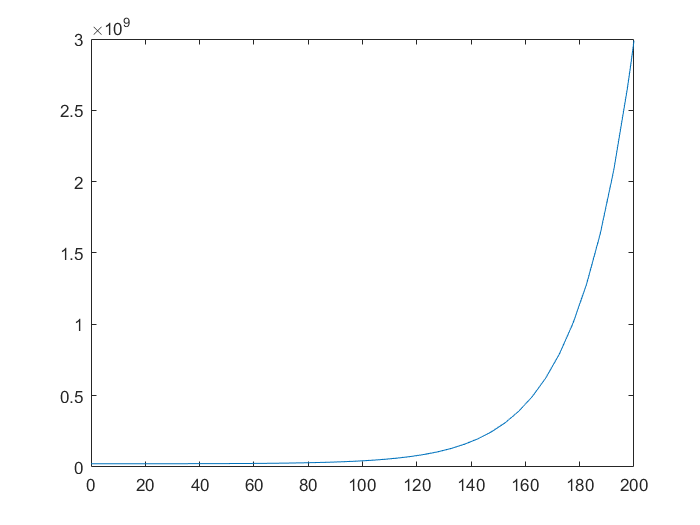

plot(t,m(:,1))

housestep(69,Uinit,OutsideAirTemp,InsolationInput,AreaofWall,AreaofWindow,Inside2InnerWallh,Inside2InnerWindowh,OuterWall2Outsideh,OuterWindow2Outsideh,HeatCapacityofAir,HeatCapacityofInteriorWall,HeatCapacityofInteriorWindow,HeatCapacityofOuterWall,HeatCapacityofOuterWindow,Inside2OuterWallr,Inside2OuterWindowr)

en2inwa = 8.6941e+05

en2inwi = 2.0125e+04

en2ouwa = 568.6348

en2ouwi = 73.4539

en2owasd = 7.6539e+06

en2owisd = 1.7717e+05

solarinputenergy = 600

InsideEnergy = 8.8893e+05

InteriorWallEnergy = -8.6884e+05

InteriorWindowEnergy = -2.0052e+04

OuterWindowEnergy = 7.6533e+06

OuterWallEnergy = 1.7710e+05

ans = 	1.0e+06 *

    0.8889
   -0.8688
   -0.0201
    7.6533
    0.1771
